Prepares the dataset and saves to a .mat file

% load all of the dataset
images = imageDatastore("data\extracted_images\", "IncludeSubfolders", true, "FileExtensions", ".jpg","LabelSource","foldernames")

images =   ImageDatastore with properties:

                       Files: {
                              ' ...\Fall 2020\QEA\QEA-Project1\data\extracted_images\!\!_100071.jpg';
                              ' ...\Fall 2020\QEA\QEA-Project1\data\extracted_images\!\!_100077.jpg';
                              ' ...\Fall 2020\QEA\QEA-Project1\data\extracted_images\!\!_100082.jpg'
                               ... and 375971 more
                              }
                     Folders: {
                              'C:\Classes\Fall 2020\QEA\QEA-Project1\data\extracted_images'
                              }
                      Labels: [!; !; ! ... and 375971 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn: @readDatas

% breakdown by label
totals = images.countEachLabel

totals = 82×2 table
    Label    Count
    _____    _____

      !       1300
      (      14294
      )      14355
      +      25112
      ,       1906
      -      33997
      0       6914
      1      26520
      2      26141
      3      10909
      4       7396
      5       3545
      6       3118
      7       2909
      8       3068
      9       3737


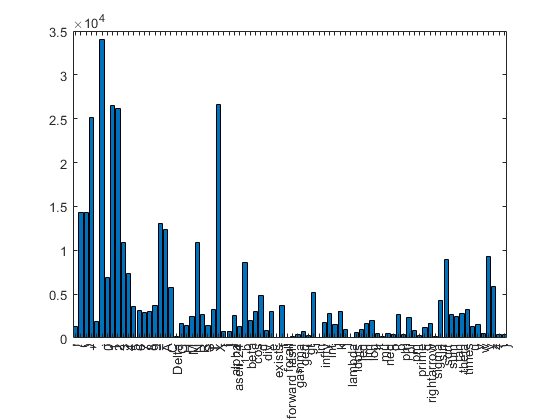

data = 375974×1 cell array
    {45×45 uint8}
    {45×45 uint8}
    {45×45 uint8}
    {45×45 uint8}
    {45×45 uint8}
    {45×45 uint8}
    {45×45 uint8}
    {45×45 uint8}
    {45×45 uint8}
    {45×45 uint8}
    {45×45 uint8}
    {45×45 uint8}
    {45×45 uint8}
    {45×45 uint8}
    {45×45 uint8}
    {45×45 uint8}


bar(categorical(totals{:,"Label"}), totals{:,"Count"});

% split into training and testing images and read
[train, test] = images.splitEachLabel(0.7);
train_labels = train.Labels;
test_labels = test.Labels;
train_images = train.readall();
test_images = test.readall();

% save to .mat
save("train.mat", "train_images", "train_labels");
save("test.mat", "test_images", "test_labels");